## 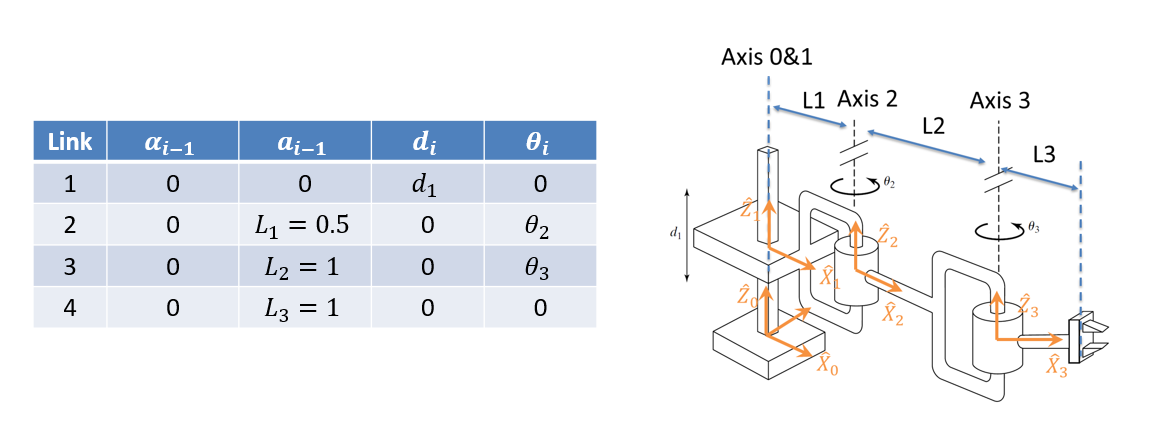

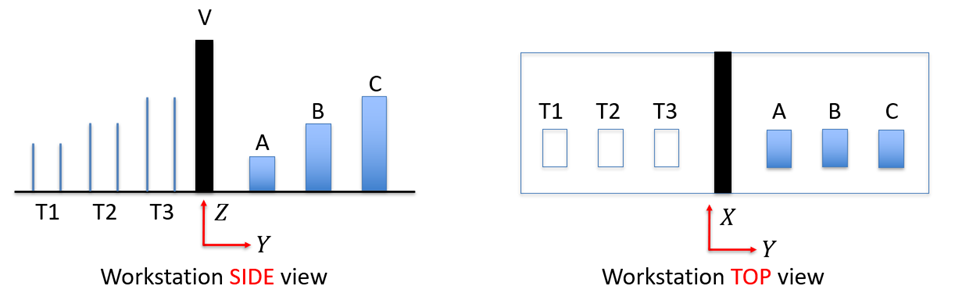

## Define robot manipulator with DH parameters and joint types

% define robot manipulator
%   DH table
%   joint types ( 0 for prismatic joint and 1 for revolute joint)
%   test_q - numeric joint configuration to test inverse kinematics
%   initial_q - numeric joint configuration 
%   mask - 6x1 position and orientation mask, set to 1 for the components we
%       would like to control; we use [1, 1, 1, 0, 0, 0]' because we only care about 
%       the position not the orientation

% prismatic, revolute, revolute manipulator
syms q1 q2 q3;
L1 = 0.5;
L2 = 1;
L3 = 1;
% set DH parameter table
DH_para = [ 0, 0, q1, 0;
    0, L1, 0, q2;
    0, L2, 0, q3;
    0, L3, 0, 0];
% set joint types
joint_types = [0; 1; 1];
% set joint configuration
test_q = [0.2, 45*pi/180, 60*pi/180]';
initial_q = [0, pi/4, pi/4]';
% set mask for position and orientation control
mask = [1, 1, 1, 0, 0, 0]';
via_pose = [0, 0, 2, 0, 0, 0]';


## Calculate robot transformation matrix and jacobian matrix

% get transformation matrix
[DH, DH_list] = DH_robot(DH_para);

Frame 1 to frame 0
DH parameters (alpha, a, d, theta):


$$\left(\begin{array}{cccc} 0 & 0 & q_{1} & 0 \end{array}\right)$$

DH transformation:


$$\left(\begin{array}{cccc} 1 & 0 & 0 & 0\\ 0 & 1 & 0 & 0\\ 0 & 0 & 1 & q_{1}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

Frame 2 to frame 1
DH parameters (alpha, a, d, theta):


$$\left(\begin{array}{cccc} 0 & \frac{1}{2} & 0 & q_{2} \end{array}\right)$$

DH transformation:


$$\left(\begin{array}{cccc} \cos\left(\frac{\pi \,q_{2}}{180}\right) & -\sin\left(\frac{\pi \,q_{2}}{180}\right) & 0 & \frac{1}{2}\\ \sin\left(\frac{\pi \,q_{2}}{180}\right) & \cos\left(\frac{\pi \,q_{2}}{180}\right) & 0 & 0\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

Frame 3 to frame 2
DH parameters (alpha, a, d, theta):


$$\left(\begin{array}{cccc} 0 & 1 & 0 & q_{3} \end{array}\right)$$

DH transformation:


$$\left(\begin{array}{cccc} \cos\left(\frac{\pi \,q_{3}}{180}\right) & -\sin\left(\frac{\pi \,q_{3}}{180}\right) & 0 & 1\\ \sin\left(\frac{\pi \,q_{3}}{180}\right) & \cos\left(\frac{\pi \,q_{3}}{180}\right) & 0 & 0\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

Frame 4 to frame 3
DH parameters (alpha, a, d, theta):


$$\left(\begin{array}{cccc} 0 & 1 & 0 & 0 \end{array}\right)$$

DH transformation:


$$\left(\begin{array}{cccc} 1 & 0 & 0 & 1\\ 0 & 1 & 0 & 0\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

DH transformation (End-effector to base):


$$\begin{array}{l} \left(\begin{array}{cccc} \sigma_{1} & -\sigma_{3}-\sigma_{2} & 0 & \cos\left(\frac{\pi \,q_{2}}{180}\right)+\cos\left(\frac{\pi \,q_{2}}{180}\right)\,\cos\left(\frac{\pi \,q_{3}}{180}\right)-\sin\left(\frac{\pi \,q_{2}}{180}\right)\,\sin\left(\frac{\pi \,q_{3}}{180}\right)+\frac{1}{2}\\ \sigma_{3}+\sigma_{2} & \sigma_{1} & 0 & \sin\left(\frac{\pi \,q_{2}}{180}\right)+\sigma_{3}+\sigma_{2}\\ 0 & 0 & 1 & q_{1}\\ 0 & 0 & 0 & 1 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\cos\left(\frac{\pi \,q_{2}}{180}\right)\,\cos\left(\frac{\pi \,q_{3}}{180}\right)-\sin\left(\frac{\pi \,q_{2}}{180}\right)\,\sin\left(\frac{\pi \,q_{3}}{180}\right)\\ \sigma_{2}=\cos\left(\frac{\pi \,q_{3}}{180}\right)\,\sin\left(\frac{\pi \,q_{2}}{180}\right)\\ \sigma_{3}=\cos\left(\frac{\pi \,q_{2}}{180}\right)\,\sin\left(\frac{\pi \,q_{3}}{180}\right) \end{array}$$

simplify(DH);

% get jacobian matrix
[Jv, Jw] = DH_jacobian(DH_para, joint_types);

Frame 1 to frame 0
DH parameters (alpha, a, d, theta):


$$\left(\begin{array}{cccc} 0 & 0 & q_{1} & 0 \end{array}\right)$$

DH transformation:


$$\left(\begin{array}{cccc} 1 & 0 & 0 & 0\\ 0 & 1 & 0 & 0\\ 0 & 0 & 1 & q_{1}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

Frame 2 to frame 1
DH parameters (alpha, a, d, theta):


$$\left(\begin{array}{cccc} 0 & \frac{1}{2} & 0 & q_{2} \end{array}\right)$$

DH transformation:


$$\left(\begin{array}{cccc} \cos\left(\frac{\pi \,q_{2}}{180}\right) & -\sin\left(\frac{\pi \,q_{2}}{180}\right) & 0 & \frac{1}{2}\\ \sin\left(\frac{\pi \,q_{2}}{180}\right) & \cos\left(\frac{\pi \,q_{2}}{180}\right) & 0 & 0\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

Frame 3 to frame 2
DH parameters (alpha, a, d, theta):


$$\left(\begin{array}{cccc} 0 & 1 & 0 & q_{3} \end{array}\right)$$

DH transformation:


$$\left(\begin{array}{cccc} \cos\left(\frac{\pi \,q_{3}}{180}\right) & -\sin\left(\frac{\pi \,q_{3}}{180}\right) & 0 & 1\\ \sin\left(\frac{\pi \,q_{3}}{180}\right) & \cos\left(\frac{\pi \,q_{3}}{180}\right) & 0 & 0\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

Frame 4 to frame 3
DH parameters (alpha, a, d, theta):


$$\left(\begin{array}{cccc} 0 & 1 & 0 & 0 \end{array}\right)$$

DH transformation:


$$\left(\begin{array}{cccc} 1 & 0 & 0 & 1\\ 0 & 1 & 0 & 0\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

DH transformation (End-effector to base):


$$\begin{array}{l} \left(\begin{array}{cccc} \sigma_{1} & -\sigma_{3}-\sigma_{2} & 0 & \cos\left(\frac{\pi \,q_{2}}{180}\right)+\cos\left(\frac{\pi \,q_{2}}{180}\right)\,\cos\left(\frac{\pi \,q_{3}}{180}\right)-\sin\left(\frac{\pi \,q_{2}}{180}\right)\,\sin\left(\frac{\pi \,q_{3}}{180}\right)+\frac{1}{2}\\ \sigma_{3}+\sigma_{2} & \sigma_{1} & 0 & \sin\left(\frac{\pi \,q_{2}}{180}\right)+\sigma_{3}+\sigma_{2}\\ 0 & 0 & 1 & q_{1}\\ 0 & 0 & 0 & 1 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\cos\left(\frac{\pi \,q_{2}}{180}\right)\,\cos\left(\frac{\pi \,q_{3}}{180}\right)-\sin\left(\frac{\pi \,q_{2}}{180}\right)\,\sin\left(\frac{\pi \,q_{3}}{180}\right)\\ \sigma_{2}=\cos\left(\frac{\pi \,q_{3}}{180}\right)\,\sin\left(\frac{\pi \,q_{2}}{180}\right)\\ \sigma_{3}=\cos\left(\frac{\pi \,q_{2}}{180}\right)\,\sin\left(\frac{\pi \,q_{3}}{180}\right) \end{array}$$

Jacobian for linear velocity (Jv):


$$\begin{array}{l} \left(\begin{array}{ccc} 0 & -\sigma_{5}-\sigma_{3}-\sigma_{2} & -\sigma_{3}-\sigma_{2}\\ 0 & \sigma_{6}+\sigma_{4}-\sigma_{1} & \sigma_{4}-\sigma_{1}\\ 1 & 0 & 0 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\sigma_{5}\,\sin\left(\frac{\pi \,q_{3}}{180}\right)\\ \sigma_{2}=\cos\left(\frac{\pi \,q_{3}}{180}\right)\,\sigma_{5}\\ \sigma_{3}=\sigma_{6}\,\sin\left(\frac{\pi \,q_{3}}{180}\right)\\ \sigma_{4}=\sigma_{6}\,\cos\left(\frac{\pi \,q_{3}}{180}\right)\\ \sigma_{5}=\sin\left(\frac{\pi \,q_{2}}{180}\right)\\ \sigma_{6}=\cos\left(\frac{\pi \,q_{2}}{180}\right) \end{array}$$

Jacobian for angular velocity (Jw):


$$\left(\begin{array}{ccc} 0 & 0 & 0\\ 0 & 0 & 0\\ 0 & 1 & 1 \end{array}\right)$$

Jacob = [Jv; Jw];

## Implement and test the inverse kinematics function

% get test pose (test_pose) corresponding to test joint configuration (test_q)
test_pose = get_pose(DH, test_q);

% get joint angle to achieve test pose
q_estimate = inverse_kinematics(DH, Jacob, test_pose, initial_q, mask);

IK converged in 480 iterations (error = 9.93e-07)


[test_q, q_estimate]

ans =     0.2000    0.2000
    0.7854    0.7854
    1.0472    1.0472


[get_pose(DH, test_q), get_pose(DH, q_estimate)]

ans =     2.4994    2.4994
    0.0457    0.0457
    0.2000    0.2000
         0         0
         0         0
    0.0320    0.0320


## Pick and drop an object with given conditions

### Set initial point, goal point, and via point (position and orientation)

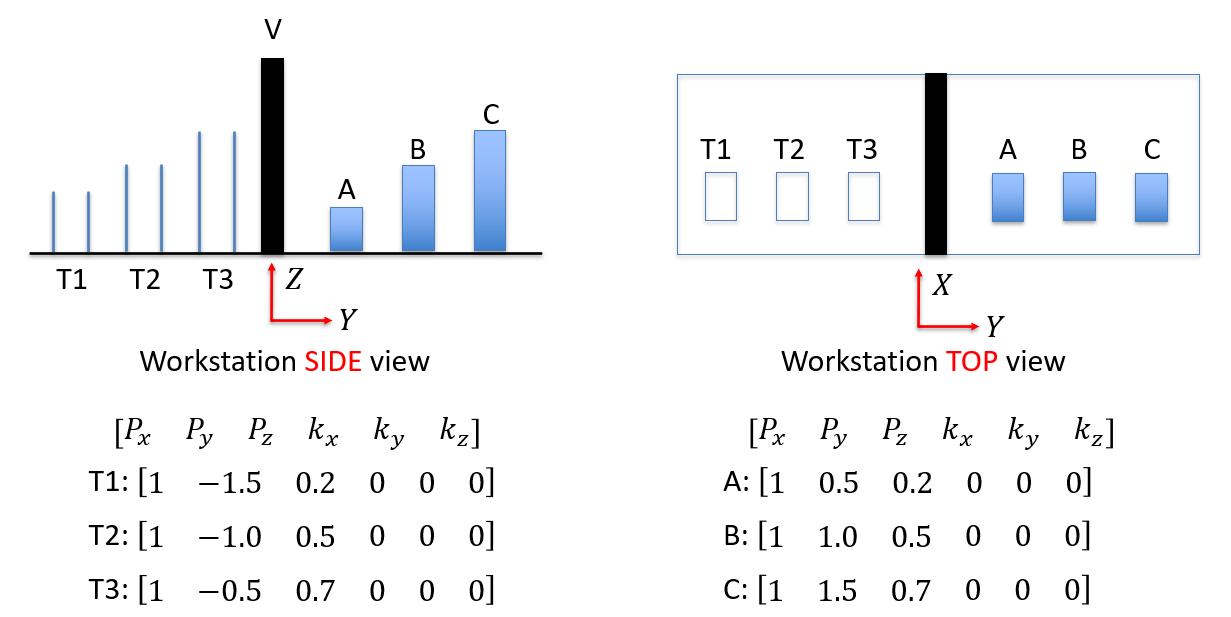

Move an object from its intial location (A, B, or C) to the goal location (T1, T2, or T3). The locations are given in position and orientation format. For the sake of simplicity, we do not need to consider the orientation in the inverse kinematics function.

% use fixed inital and target pose
object = 3;
goal = 3;

if object == 1
    initial_pose = [1, 0.5, 0.2, 0, 0, 0]';
elseif object == 2
    initial_pose = [1, 1, 0.2, 0, 0, 0]';
elseif object == 3
    initial_pose = [1, 1.5, 0.2, 0, 0, 0]';
end
if goal == 1
    target_pose = [1, -1.5, 0.2, 0, 0, 0]';
elseif goal == 2
    target_pose = [1, -1, 0.2, 0, 0, 0]';
elseif goal == 3
    target_pose = [1, -0.5, 0.2, 0, 0, 0]';
end


### Calculate the joint configurations for initial, goal, and via points using inverse kinematics

% get joint configurations using inverse kinematics
q_init = inverse_kinematics(DH, Jacob, initial_pose, initial_q, mask);

IK converged in 823 iterations (error = 9.92e-07)


q_goal = inverse_kinematics(DH, Jacob, target_pose, initial_q, mask);

IK converged in 802 iterations (error = 9.91e-07)


q_via = inverse_kinematics(DH, Jacob, via_pose, initial_q, mask);

IK converged in 807 iterations (error = 9.85e-07)



disp('Joint configurations (intial, goal, and via points):')

Joint configurations (intial, goal, and via points):


[q_init, q_goal, q_via]

ans =     0.2000    0.2000    2.0000
 -250.6737   24.2952 -255.5225
  284.4774  221.4096  511.0449


disp('Initial pose vs its reachable pose:')

Initial pose vs its reachable pose:


[initial_pose, get_pose(DH, q_init)]

ans =     1.0000    1.0000
    1.5000    1.5000
    0.2000    0.2000
         0         0
         0         0
         0    0.5900


disp('Target pose vs its reachable pose:')

Target pose vs its reachable pose:


[target_pose, get_pose(DH, q_goal)]

ans =     1.0000    1.0000
   -0.5000   -0.5000
    0.2000    0.2000
         0         0
         0         0
         0   -1.9948


### Trajectory planning in the joint space using linear function

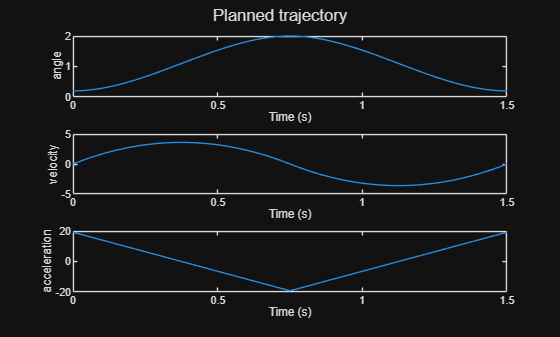

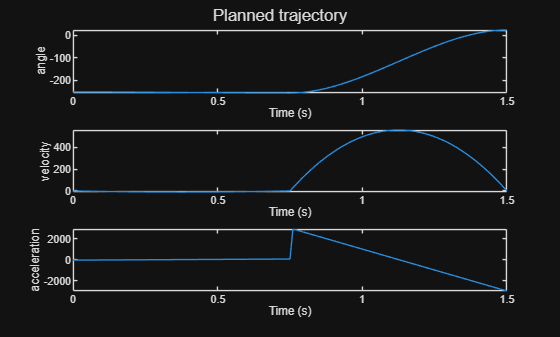

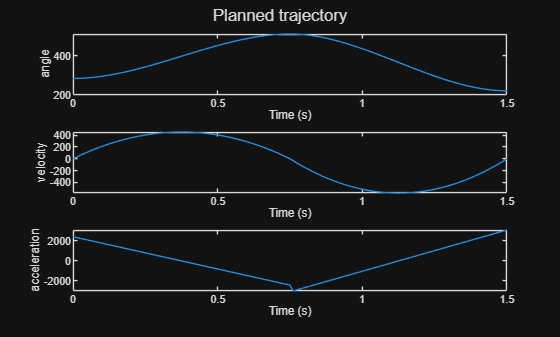

% trajectory planning for each joint separately to get joint angle, joint velocity, and joint acceleration
trajectory = cell(3, length(joint_types));
% go through each joint
for k = 1:length(q_init)
    t1 = 1.5;
    q0 = q_init(k);
    q1 = q_goal(k);
    q_mid = q_via(k);
    q0_dot = 0;
    q1_dot = 0;
    [qt, qt_dot, qt_ddot, ts] = trajectory_planning(q0, q0_dot, q1, q1_dot, q_mid, t1);
    trajectory{1, k} = qt;
    trajectory{2, k} = qt_dot;
    trajectory{3, k} = qt_ddot;
end

% get joint angle trajectory
q_trajectory = cell2mat(trajectory(1, :)');

### Calculate the end-effector trajectory using forward kinematics

% get end-effector pose trajectory corresponding to the planned joint angle trajectory
sample_count = size(q_trajectory, 2);
task_trajecotry = zeros(6, sample_count);
% go through each sample point
for ti = 1:sample_count
    q_pose = get_pose(DH, q_trajectory(:, ti));
    task_trajecotry(:, ti) = q_pose;
end
% extract end-effector position trajectory
task_position = task_trajecotry(1:3, :);

### Plot the end-effector trajectory

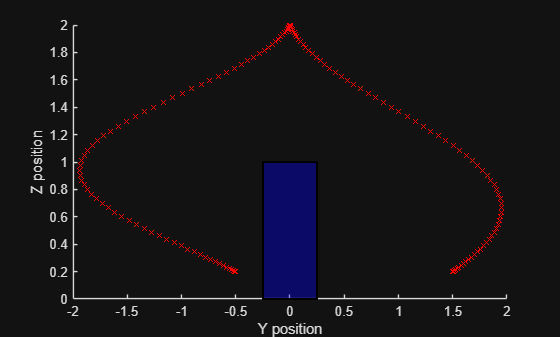

% Rectangular prism centered at (1, 0, 1)
cx = 1; cy = 0; cz = 0.5;
dx = 1;      % half of x length (2/2)
dy = 0.25;   % half of y length (0.5/2)
dz = 0.5;      % half of z length (1/2)

% 8 vertices
V = [
    cx-dx, cy-dy, cz-dz;  % 1
    cx+dx, cy-dy, cz-dz;  % 2
    cx+dx, cy-dy, cz+dz;  % 3
    cx-dx, cy-dy, cz+dz;  % 4
    cx-dx, cy+dy, cz-dz;  % 5
    cx+dx, cy+dy, cz-dz;  % 6
    cx+dx, cy+dy, cz+dz;  % 7
    cx-dx, cy+dy, cz+dz   % 8
];

% Faces
F = [
    1 2 3 4;  % bottom
    5 6 7 8;  % top
    1 2 6 5;  % back
    4 3 7 8;  % front
    1 4 8 5;  % left
    2 3 7 6   % right
];

figure();
plot3(task_position(1, :),task_position(2, :),task_position(3, :), 'rx');
xlabel('X position');
ylabel('Y position');
zlabel('Z position');

patch('Faces', F, 'Vertices', V, ...
    'FaceColor', 'b', 'FaceAlpha', 0.2, ...
    'EdgeColor', 'k', 'LineWidth', 1.5);
view(90,0); % view Y-Z plane

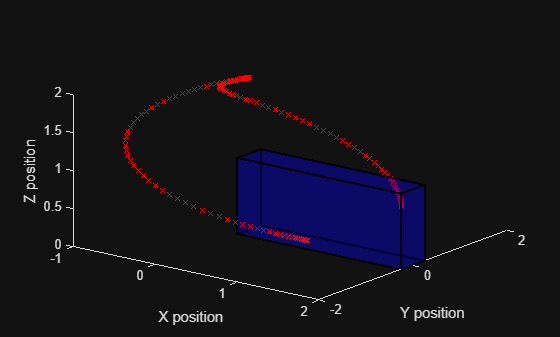


figure();
plot3(task_position(1, :),task_position(2, :),task_position(3, :), 'rx');
xlabel('X position');
ylabel('Y position');
zlabel('Z position');
patch('Faces', F, 'Vertices', V, ...
    'FaceColor', 'b', 'FaceAlpha', 0.2, ...
    'EdgeColor', 'k', 'LineWidth', 1.5);
view(37.5, 30); % Isometric View